clc;clear all;close all
%% N=5;A=[0 1;-3 -5];B=[0;1];C=[1 0];D=[0]
%% Ts=0.2;   %tf=1  Qy,R   %yrefk=1;    %(y-yref)'*Qy*(y-yref)+u'Ru
N=5;
Ts=0.2;

R=5;
C=0.002;
Kw=3;
L=0.001;
Kt=Kw;
Ke=Kt

Ke = 3

J=0.01;

N=5;
Ts=0.2;
A=[-1/(R*C) -1/C 0;
Kw/(L*Kw+Kt*Ke) 0 -Ke*Kw/(L*Kw+Kt*Ke);
0 Kt/J 0]

A =  -100.0000 -500.0000         0
    0.3332         0   -0.9997
         0  300.0000         0


B=[1/(R*C);0;0];C=[0 0 1];D=0;

%Fcosto  Qbig, q
Qf=10000;
Qy=100;
R=0.1;
C'*Qy*C

ans =      0     0     0
     0     0     0
     0     0   100


dC=diag(C'*Qy*C)

dC =      0
     0
   100


%Qbig=diag([dC;dC;dC;dC;dC])
nx=3;
Qbig=blkdiag(kron(eye(N),C'*Qy*C),kron(eye(N),R))

Qbig =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0 

Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx))=C'*Qy*C+C'*Qf*C

Qbig = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0100         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

yrefk=1;
q=-[C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk;C'*Qy*yrefk+C'*Qf*yrefk;0;0;0;0;0]

q =      0
     0
  -100
     0
     0
  -100
     0
     0
  -100
     0


id=eye(3)

id =      1     0     0
     0     1     0
     0     0     1


ze=zeros(3);
zeB=0*B;
%Ad=A*Ts+id
%Ad=expm(A*Ts)
%Bd=B*Ts
%Bd=expm(A*Ts)*A\(eye(2)-expm(-A*Ts))*B
%Bd=A\(expm(A*Ts)-eye(3))*B
Gz=c2d(ss(A,B,C,D),Ts,'zoh')

Gz =
 
  A = 
              x1         x2         x3
   x1    0.01417      4.186    -0.0415
   x2   -0.00279    -0.7981    0.01667
   x3  -0.008299     -5.002     -0.812
 
  B = 
              u1
   x1     0.9997
   x2  -0.002766
   x3     0.6123
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


Gss=ss(Gz)

Gss =
 
  A = 
              x1         x2         x3
   x1    0.01417      4.186    -0.0415
   x2   -0.00279    -0.7981    0.01667
   x3  -0.008299     -5.002     -0.812
 
  B = 
              u1
   x1     0.9997
   x2  -0.002766
   x3     0.6123
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


Ad=expm(A*Ts)

Ad =     0.0142    4.1859   -0.0415
   -0.0028   -0.7981    0.0167
   -0.0083   -5.0021   -0.8120


Bd=A\(expm(A*Ts)-eye(3))*B

Bd =     0.9997
   -0.0028
    0.6123


## Sin restricciones


Aeq=[-id ze ze ze ze Bd zeB zeB zeB zeB;
     Ad -id ze ze ze zeB Bd zeB zeB zeB;
     ze Ad -id ze ze zeB zeB Bd zeB zeB;
     ze ze Ad -id ze zeB zeB zeB Bd zeB;
     ze ze ze Ad -id zeB zeB zeB zeB Bd;]

Aeq =    -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9997         0         0         0         0
         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0028         0         0         0         0
         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0    0.6123         0         0         0         0
    0.0142    4.1859   -0.0415   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0    0.9997         0         0         0
   -0.0028   -0.7981    0.0167         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0   -0.0028         0         0

x0=[0;0;0];
zex0=0*x0;
beq=[-Ad*x0;zex0;zex0;zex0;zex0]

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z=quadprog(Qbig,q,[],[],Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =     1.6216
   -0.0045
    0.9932
    2.8834
    0.0075
    0.9912
    3.0636
   -0.0059
    0.9909
    2.9026


nu=1;
X=z(1:(nx*N))

X =     1.6216
   -0.0045
    0.9932
    2.8834
    0.0075
    0.9912
    3.0636
   -0.0059
    0.9909
    2.9026


U=z((nx*N)+(1:(nu*N)))

U =     1.6222
    2.9214
    3.0334
    2.9261
    3.0246


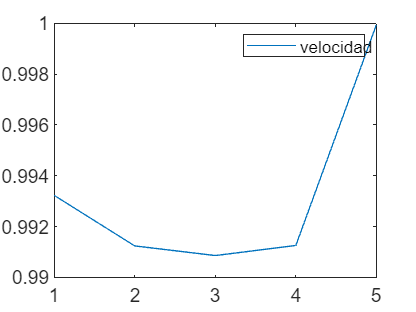

figure
plot(X(3:3:end));
legend('velocidad')

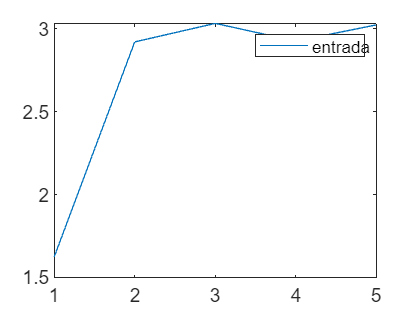

figure
plot(U)
legend('entrada')

## Con restricciones


ze = zeros(1,nx)

ze =      0     0     0


zeB = zeros(1,nu)

zeB = 0


Umax = [1]; %-----> tamaño nu numero de entradas en fila
Xmax = [0 1 0]; %----> tamaño de estados fila
Xmin = [0 -1 0]

Xmin =      0    -1     0


Ades=[ ze ze ze ze ze  Umax zeB zeB zeB zeB;
       ze ze ze ze ze  zeB Umax zeB zeB zeB;
       ze ze ze ze ze  zeB zeB Umax zeB zeB;
       ze ze ze ze ze  zeB zeB zeB Umax zeB;
       ze ze ze ze ze  zeB zeB zeB zeB Umax;

      Xmax ze ze ze ze  zeB zeB zeB zeB zeB;
      ze Xmax ze ze ze  zeB zeB zeB zeB zeB;
      ze ze Xmax ze ze  zeB zeB zeB zeB zeB;
      ze ze ze Xmax ze  zeB zeB zeB zeB zeB;
      ze ze ze ze Xmax  zeB zeB zeB zeB zeB;

      Xmin ze ze ze ze  zeB zeB zeB zeB zeB;
      ze Xmin ze ze ze  zeB zeB zeB zeB zeB;
      ze ze Xmin ze ze  zeB zeB zeB zeB zeB;
      ze ze ze Xmin ze  zeB zeB zeB zeB zeB;
      ze ze ze ze Xmin  zeB zeB zeB zeB zeB;]

Ades =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0 


bdes=[ 2.8*ones(N,1); % ---> primera restriccion
       4e-3*ones(N,1); % ----> Segunda restriccion
       1e-3*ones(N,1)]; % -----> tercera restriccion

z=quadprog(Qbig,q,Ades,bdes,Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =     0.3614
   -0.0010
    0.2213
    1.6104
   -0.0010
    0.8137
    2.6769
    0.0024
    0.9798
    2.7631


X=z(1:(nx*N))

X =     0.3614
   -0.0010
    0.2213
    1.6104
   -0.0010
    0.8137
    2.6769
    0.0024
    0.9798
    2.7631


X=reshape(X,[nx N])

X =     0.3614    1.6104    2.6769    2.7631    2.7997
   -0.0010   -0.0010    0.0024   -0.0007   -0.0006
    0.2213    0.8137    0.9798    0.8580    0.9983


U=z((nx*N)+(1:(nu*N)))

U =     0.3615
    1.6192
    2.6929
    2.7566
    2.8000


U=reshape(U,[nu N])

U =     0.3615    1.6192    2.6929    2.7566    2.8000


Vc=X(1,:)

Vc =     0.3614    1.6104    2.6769    2.7631    2.7997


I=X(2,:)

I =    -0.0010   -0.0010    0.0024   -0.0007   -0.0006


Vel=X(3,:)

Vel =     0.2213    0.8137    0.9798    0.8580    0.9983


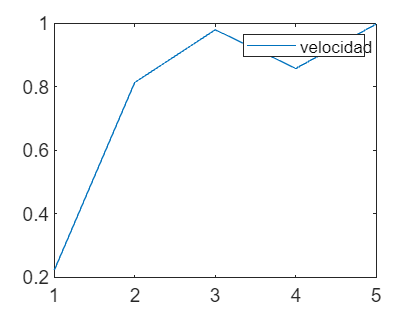

figure
plot(Vel);hold on
legend('velocidad')

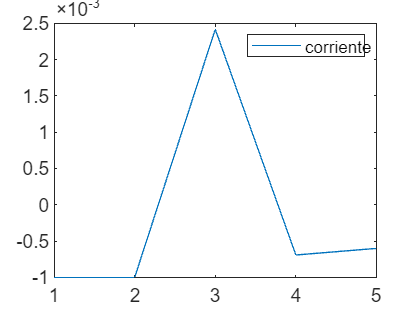

figure
plot(I)
legend('corriente')

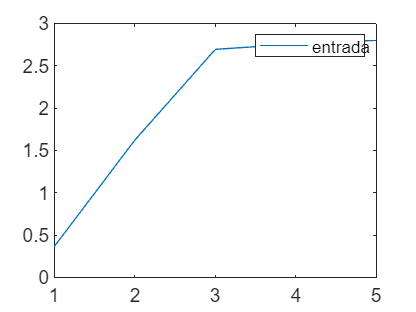

figure
plot(U)
legend('entrada')